# Laboratorio 1 de señales

Se tomaron los respectivos datos usando una stm32 y su sensor análogo, con una función senosoidal configurada en el generador del laboratorio como se especifica en la guía.

Se tomaron muestras a una frecuencia de doscientas por segundo

Por lo que cada muestra tiene un espacio de 5ms.

Para el ejercicio propuesto se van a trabajar todos los vectores con 200 muestras (puede variar según el tiempo que se quiera graficar)

El objetivo es ver los errores de cuantificación para observar cómo afecta la resolución del sensor en la toma de muestras

archivos=["datos10hz.txt","datos20hz.txt","datos30hz.txt","datos40hz.txt",...
    "datos10hz02.txt","datos20hz02.txt","datos30hz02.txt","datos40hz02.txt",...
    "datos50hz.txt","datos60hz.txt","datos70hz.txt", ...
    "datos80hz.txt","datos90hz.txt","datos100hz.txt",...
    "datos80hz02.txt","datos90hz02.txt","datos100hz02.txt",...
    "datos100hzreset01.txt","datos100hzreset02.txt","datos100hzreset03.txt"];

frecuenciaMuestreo      =200;%[Hz]
frecuenciaSenal         =30;%[Hz]
tiempoGrafica           =0.3;%[s]


Seleccione el archivo de muestras a graficar:

archivoAnalizado=archivos(3);

                  

%recuperar los datos del archivo
[datosAdc,~]=importdata(archivoAnalizado);
datosAdc=datosAdc';
numeroMuestras = tiempoGrafica*frecuenciaMuestreo;

%creamos un vector de tiempo para el eje x
t=0:1/frecuenciaMuestreo:tiempoGrafica; %[s]

%recortar los datos
datosAdc=datosAdc(250:250+numeroMuestras);


%calculamos frecuencia angular
frecuenciaAngular=double(2*pi()*frecuenciaSenal);

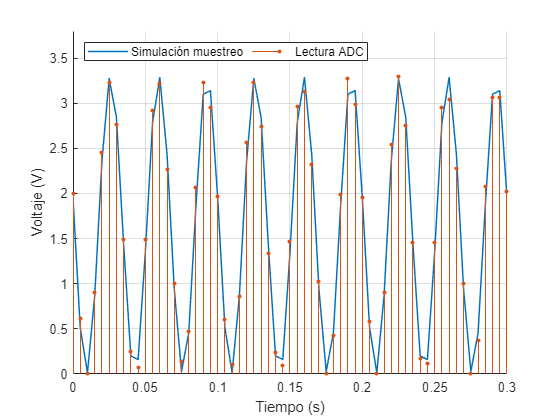

fase = 2.9584;

%se hace la simulación de muestreo
datosSim=1.65*sin(frecuenciaAngular.*t+fase)+1.65;

figure
grid on
hold on
xlabel("Tiempo (s)")
ylabel("Voltaje (V)")
ylim([0 3.8 ])
plot(t,datosSim,LineWidth=1.1)
stem(t,datosAdc, LineWidth=0.05,MarkerSize=9,Marker=".")
legend('Simulación muestreo','Lectura ADC', ...
    'Location','northwest','Orientation','horizontal')


valorPsnr=psnr(datosAdc,datosSim)

valorPsnr = 19.2882

ErrorCuadraticoMedio=immse(datosAdc,datosSim)

ErrorCuadraticoMedio = 0.0118


%calcul de la media
mediaTeorica=mean(datosSim)

mediaTeorica = 1.6549

mediaExperimental=mean(datosAdc)

mediaExperimental = 1.6708

ErrorEstimacion=(abs(mediaTeorica-mediaExperimental))/mediaTeorica

ErrorEstimacion = 0.0096


%calculo de la varianza
varianzaExperimental=var(datosAdc)

varianzaExperimental = 1.3331

varianzaSimulacion=var(datosSim)

varianzaSimulacion = 1.3627

ErrorVarianzas=(abs(varianzaExperimental-varianzaSimulacion))/varianzaSimulacion

ErrorVarianzas = 0.0217